% Script to compare two transfer functions
% Preliminary: Clear all variables, clear command window, close all figures
clear
clc
close all

% Change the output format to make numbers easier to read
format shortEng;

% Create a special variable s that you can use in the following transfer
% function. Alternatively you could just use g = tf(numerator,denominator).
s = tf('s');

Vin = 15;
L = 42e-6;
C = 230e-6;
R = 5;

w0_ideal = 1/sqrt(L*C);   % Resonance Frequency
Q_ideal = R*sqrt(C/L);   % Quality factor
D_ideal = 1/(2*Q_ideal);       % Dämpfungsgrad
G_ideal = tf(Vin, [L*C, L/R, 1])

G_ideal =
 
               15
  ----------------------------
  9.66e-09 s^2 + 8.4e-06 s + 1
 
Continuous-time transfer function.
Model Properties



% Refined modeling
R_C = 0.2; %--> anpassen zwischen 0.1 und 0.5 Ohm
w0_refined = 1/sqrt(L*C) * sqrt(1/(1+R_C/R));
Q_refined = (1/w0_refined)*(1/((L/R)+C*R_C));
wz_refined = 1/(R_C*C);
G_refined = tf([Vin/wz_refined, Vin], [1/w0_refined^2, 1/(w0_refined*Q_refined), 1])

G_refined =
 
          0.00069 s + 15
  ------------------------------
  1.005e-08 s^2 + 5.44e-05 s + 1
 
Continuous-time transfer function.
Model Properties


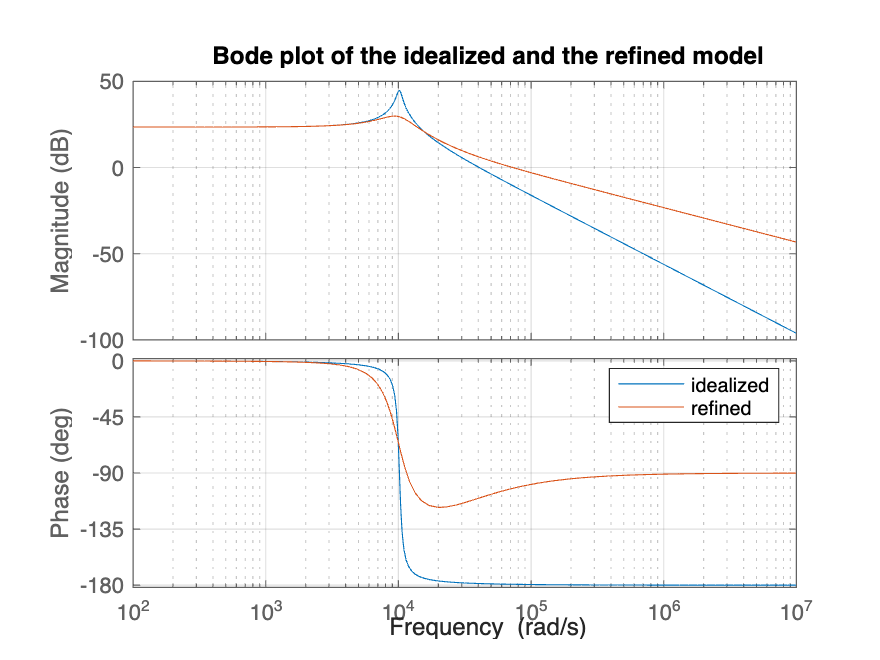


% Compare in the bode plot
figure; 
hold on
bode(G_ideal, {1e2,1e7})
bode(G_refined, {1e2,1e7})
grid on
title('Bode plot of the idealized and the refined model')
legend('idealized', 'refined')
hold off

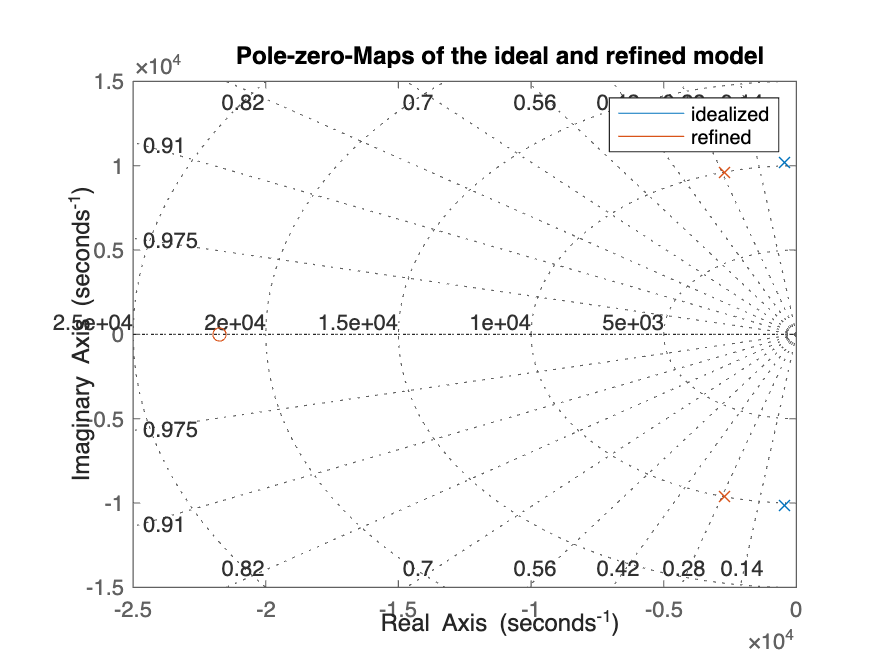


% PZ - MAPS
figure;
hold on
pzmap(G_ideal, G_refined);
grid on
title('Pole-zero-Maps of the ideal and refined model');
legend('idealized','refined');
hold off;

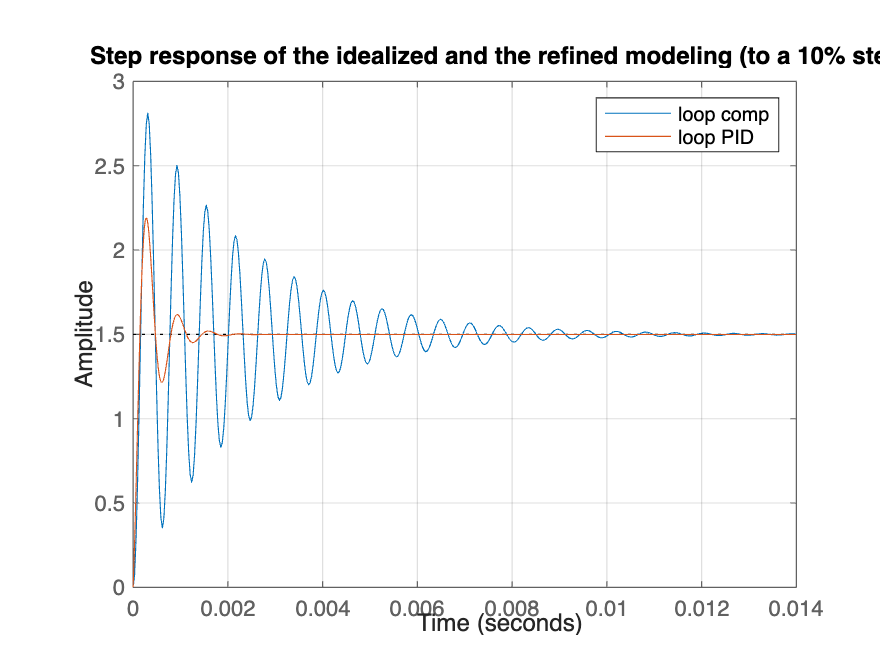


% Compare the step responses
figure;
step(0.1*G_ideal, 0.1*G_refined)
grid on
title('Step response of the idealized and the refined modeling (to a 10% step)');
legend('loop comp','loop PID')